# Rotary Inverted Pendulum

## Motor Parameters

D = 0.0058976

D = 0.0059

J = 0.0006239

J = 6.2390e-04

Kb = 0.12219

Kb = 0.1222

Kt = 0.028632

Kt = 0.0286

L = 0.23259

L = 0.2326

R = 2.1695

R = 2.1695


motor_b = D        ;          % Damping Coefficient
motor_j = J        ;          % System Inertia
motor_km = Kb        ;        % Motor speed constant
motor_kt = Kt         ;       % Motor Torque constant
motor_l = L      ;            % Motor Resistance
motor_effeciency = 0.69   ;   % Motor effeciency
gear_box_effeciency = 1 ;     % Gearbox Effeciency
gear_box_ratio = 1      ;     % Motor gearbox ratio 


## System Parameters


m_pendulum = 50/1000 ;  %the mass of pendulum in gram
r = 60/1000          ;  %length of arm in mm
l = (145.5/1000)/2      ;  %length of arm of pendulum in mm


## State Space Parameters

a=motor_j+(m_pendulum*r*r);
b=m_pendulum*l*r;
c=(4/3)*m_pendulum*l*l;
d=m_pendulum*9.8*l;

E=(a*c)-(b*b);
G = ((motor_effeciency*gear_box_effeciency*motor_km*motor_kt*(gear_box_ratio*gear_box_ratio))-(motor_b*motor_r))/(motor_r);

H= (motor_effeciency*gear_box_effeciency*motor_kt*gear_box_ratio)/(motor_r*E);


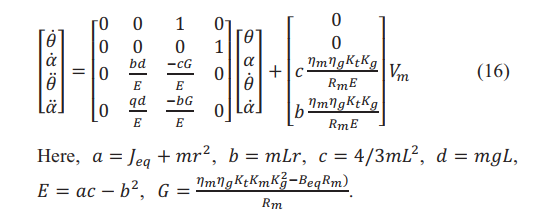

## State Space

A_mat=[0 0 1 0;0 0 0 1;0 (b*d)/(E) (-(c*G)/E) 0 ; 0 ((a*d)/E) (-b*G)/E 0 ]; % system matrix
B_mat=[0;0;(c)*(H);(b)*(H)];                                                % input matrix  
C_mat=[1 0 0 0 ; 0 1 0 0];                                                  % output matrix
D_mat=[0;0];                                                                % feedforward matrix

state_space_model=ss(A_mat,B_mat,C_mat,D_mat)                              % State space object


state_space_model =
 
  A = 
          x1     x2     x3     x4
   x1      0      0      1      0
   x2      0      0      0      1
   x3      0  32.96  7.153      0
   x4      0  121.4  4.425      0
 
  B = 
          u1
   x1      0
   x2      0
   x3  13.61
   x4  8.421
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


## LQR Parameters

q=diag([   10     1000      1000         400      ]);
%      [   theta   alpha   thetadot   alphadot    ]
r_eq=5;

k=lqr(state_space_model,q,r_eq);
    
k_theta=k(1)

k_theta = -1.4142

k_alpha=k(2)

k_alpha = 499.2785

k_thetadot=k(3)

k_thetadot = -13.9200

k_alphadot=k(4) 

k_alphadot = 50.2140

## Step response

LQR_sys=ss(A_mat-B_mat*k,B_mat,C_mat,0)


LQR_sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3   19.25   -6764   196.7  -683.6
   x4   11.91   -4083   121.6  -422.8
 
  B = 
          u1
   x1      0
   x2      0
   x3  13.61
   x4  8.421
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


TF = tf(LQR_sys)


TF =
 
  From input to output...
               13.61 s^2 - 1.233e-12 s - 1375
   1:  ----------------------------------------------
       s^4 + 226.2 s^3 + 4064 s^2 + 1.987e04 s + 1945
 
            8.421 s^2 - 6.155e-13 s - 3.847e-14
   2:  ----------------------------------------------
       s^4 + 226.2 s^3 + 4064 s^2 + 1.987e04 s + 1945
 
Continuous-time transfer function.
Model Properties


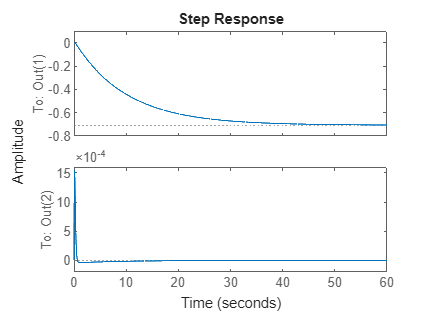

step(TF)